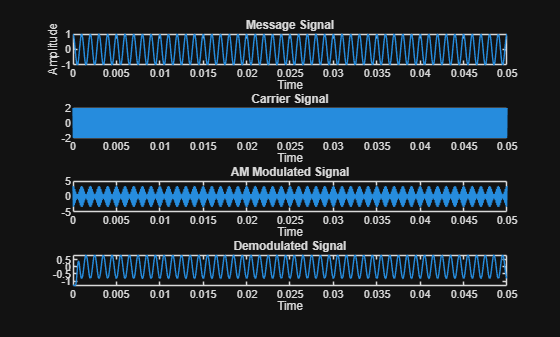

clc;
clear;
close all;

%% PARAMETERS
Fs = 100e3;            % Sampling frequency (100 kHz)
t = 0:1/Fs:0.05;       % Time vector (50 ms)

fm = 1e3;              % Message frequency (1 kHz)
fc = 10e3;             % Carrier frequency (10 kHz)

Am = 1;                % Message amplitude
Ac = 2;                % Carrier amplitude

mu = 0.7;              % Modulation index (0 < mu <= 1)

%% MESSAGE SIGNAL
m = Am * cos(2*pi*fm*t);

%% CARRIER SIGNAL
c = Ac * cos(2*pi*fc*t);

%% AM MODULATION (DSB-FC)
s = Ac * (1 + mu*m) .* cos(2*pi*fc*t);

%% DEMODULATION (ENVELOPE DETECTION)

% Envelope using absolute value + low-pass filter
env = abs(s);

% Low-pass filter
Wn = (2*fm)/(Fs/2);       % Cutoff just above message freq
b = fir1(100, Wn);
demod = filter(b, 1, env);

% Remove DC component
demod = demod - mean(demod);

%% PLOTS

figure;

subplot(4,1,1);
plot(t, m);
title('Message Signal');
xlabel('Time');
ylabel('Amplitude');

subplot(4,1,2);
plot(t, c);
title('Carrier Signal');
xlabel('Time');

subplot(4,1,3);
plot(t, s);
title('AM Modulated Signal');
xlabel('Time');

subplot(4,1,4);
plot(t, demod);
title('Demodulated Signal');
xlabel('Time');

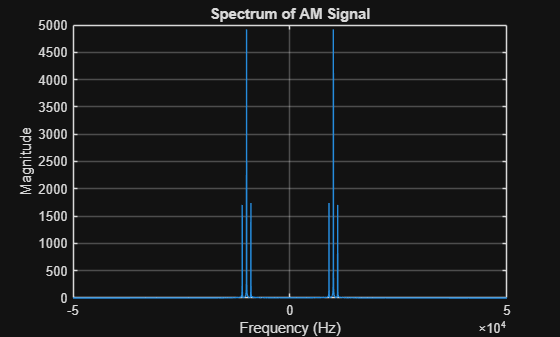


%% FREQUENCY DOMAIN (OPTIONAL)

figure;

N = length(s);
f = (-N/2:N/2-1)*(Fs/N);

S = fftshift(abs(fft(s)));

plot(f, S);
title('Spectrum of AM Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;